# Лабораторная работа №6

Решение задачи Коши для обыкновенных дифференциальных уравнений многошаговым методом Адамса 2-3 порядка.

ДУ:  $y\prime -\frac{y{\left(2x-5\right)}}{x^2 }=5$ 

Задача Коши: $y{\left(2\right)}=4$ $x\in {\left[2;6\right]}$

Входные данные:

f = @(x, y) 5 + (y*(2*x-5))/(x.^2);
% f = @(x, y) -y; %для теста
a = 2;
b = 6;
n = 1000;
y_0 = 4;
[x, S1] = runge_kuta(f, a, b, n, y_0);
RUNGE_KUTA = S1

RUNGE_KUTA =     4.0000    4.0160    4.0321    4.0481    4.0643    4.0804    4.0966    4.1128    4.1290    4.1453    4.1616    4.1779    4.1943    4.2107    4.2271    4.2436    4.2601    4.2766    4.2932    4.3098    4.3264    4.3431    4.3597    4.3765    4.3932    4.4100    4.4268    4.4437    4.4605    4.4775    4.4944    4.5114    4.5284    4.5454    4.5625    4.5796    4.5967    4.6139    4.6311    4.6483    4.6656    4.6829    4.7002    4.7176    4.7350    4.7524    4.7699    4.7873    4.8049    4.8224


[x, S2] = adams(f, a, b, n, 1.649, 1);
ADAMS = S2

ADAMS =     1.6490    1.0000    1.0191    1.0381    1.0571    1.0761    1.0950    1.1140    1.1330    1.1520    1.1709    1.1899    1.2089    1.2278    1.2468    1.2657    1.2847    1.3036    1.3226    1.3415    1.3604    1.3794    1.3983    1.4173    1.4362    1.4552    1.4741    1.4930    1.5120    1.5309    1.5499    1.5688    1.5878    1.6068    1.6257    1.6447    1.6637    1.6826    1.7016    1.7206    1.7396    1.7586    1.7775    1.7965    1.8155    1.8346    1.8536    1.8726    1.8916    1.9106


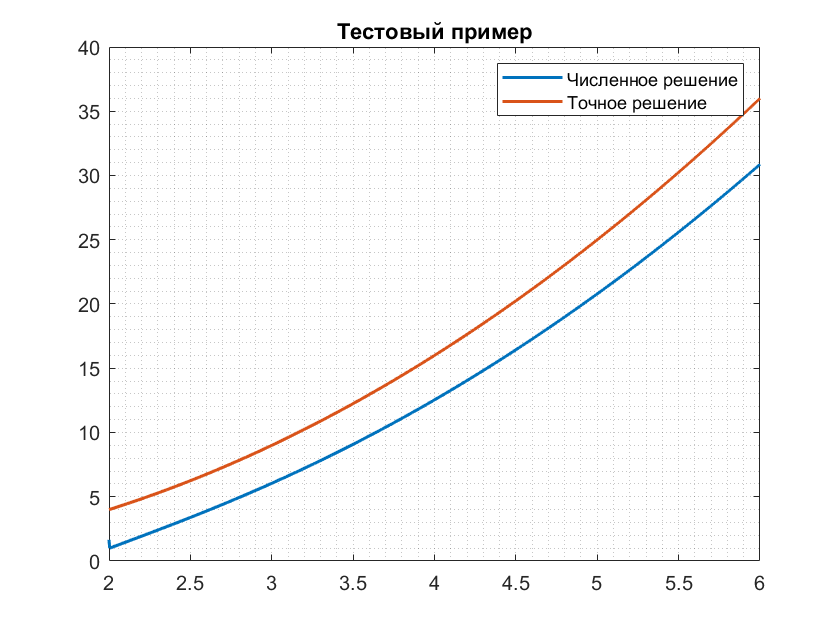

x1 = linspace(a, b, n+1);
% x1 = linspace(a, b, 100);
y1 = x.^2;
% pogresh_runge_kuta = max(abs(S1 - y1))
% pogresh_adams = max(abs(S2 - y1))
figure
plot(x, S2, 'LineWidth', 1.5)
hold on
plot(x1, y1, 'LineWidth', 1.5)
grid minor
legend('Численное решение', 'Точное решение')
title('Тестовый пример')

T = table(x', S2', abs(S2'-y1'))

T = 1001×3 table
    Var1      Var2      Var3 
    _____    ______    ______

        2     1.649     2.351
    2.004         1     3.016
    2.008    1.0191     3.013
    2.012    1.0381    3.0101
    2.016    1.0571    3.0072
     2.02    1.0761    3.0043
    2.024     1.095    3.0015
    2.028     1.114    2.9988
    2.032     1.133     2.996
    2.036     1.152    2.9933
     2.04    1.1709    2.9907
    2.044    1.1899     2.988
    2.048    1.2089    2.9855
    2.052    1.2278    2.9829
    2.056    1.2468    2.9804
     2.06    1.2657    2.9779


writetable(T, 'data.xlsx', 'Sheet', 1, 'Range', 'D1', ...
    'WriteRowNames', true)

Построение графиков точного и численного решения.

figure
hold on
grid minor
h = [1, 2, 3, 10, 20];
lstr = [];
f = @(x,y) 5 + (y*(2*x-5))/(x.^2);
for i = 1:5
    [x, S1] = runge_kuta(f, a, b, h(i), y_0);
    [x, S2] = adams(f, a, b, h(i), y_0, S1(2));
    plot(x, S2, 'LineWidth', 1.5);
    lstr = [lstr, "h = " + num2str(1/h(i))];
end
plot(x1, y1, 'LineWidth', 1.5);
title('Графики численного и точного решений')
lstr = [lstr, "Точное решение"]

lstr = 1×6 string array
    "h = 1"    "h = 0.5"    "h = 0.33333"    "h = 0.1"    "h = 0.05"    "Точное решение"


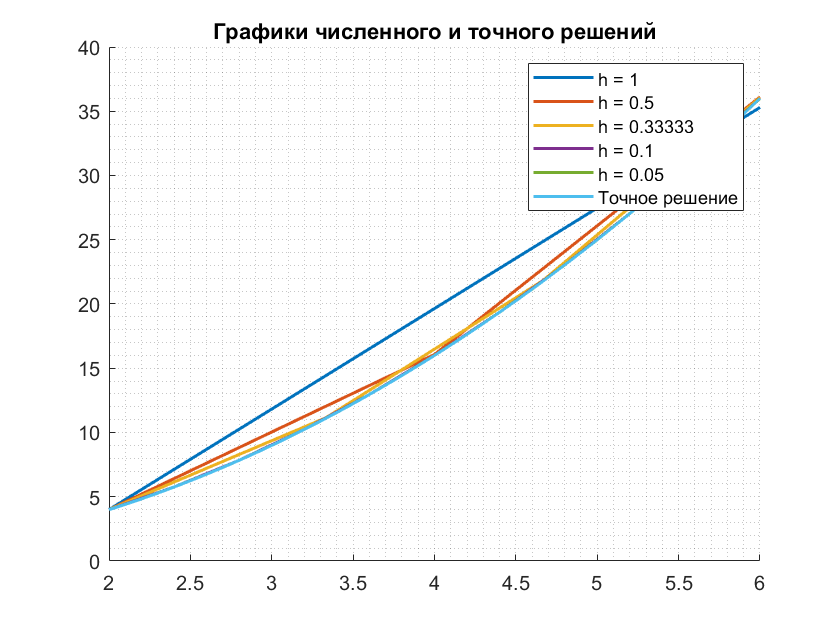

legend(lstr)

Построение зависимости погрешности метода от шага:

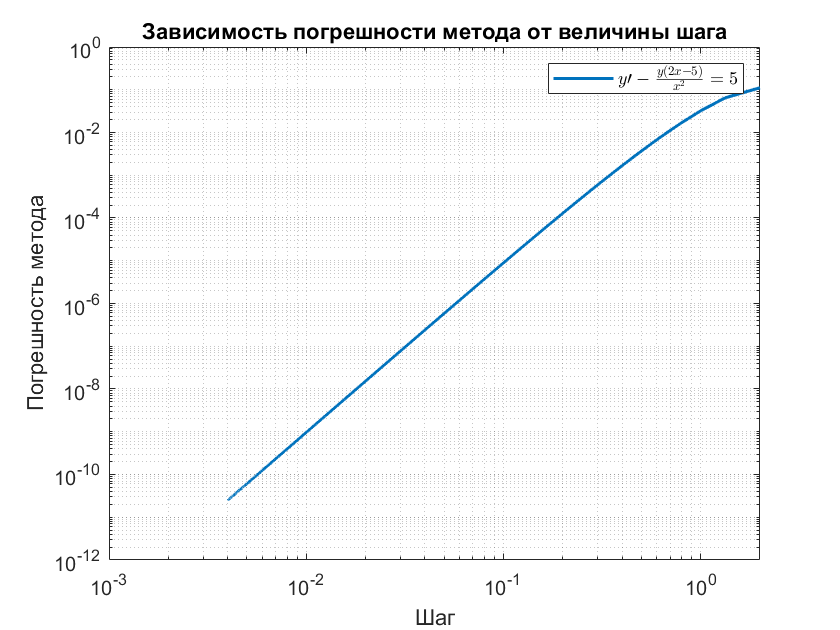

nmax = 1000;
 

f = @(x,y) 5 + (y*(2*x-5))/(x.^2);
Err = [];
E = [];
H = [];

parfor j = 2:nmax
    [x, S1] = runge_kuta(f, a, b, j, y_0);
    [x, S2] = adams(f, a, b, j, y_0, S1(2));
    x1 = linspace(a, b, j+1);
    y1 = x1.^2;
    E(j) = max(abs(S2 - y1));
    H(j) = (b-a)/j;
end

figure
loglog(H, E, 'LineWidth', 1.5);
grid minor
xlabel('Шаг')
ylabel('Погрешность метода')
title("Зависимость погрешности метода от величины шага")
legend("$y\prime -\frac{y{\left(2x-5\right)}}{x^2 }=5$", 'interpreter', 'latex')

Блок функций:

function [x, y] = runge_kuta(f, a, b, n, y_2)
    h = (b-a)/n;
    x = linspace(a, b, n+1);
    y = [];
    y(1) = y_2; 
    for i = 1:n
        K1 = f(x(i), y(i));
        K2 = f((x(i)+h/2), (y(i)+(h/2)*K1));
        K3 = f((x(i)+h),(y(i)-h*K1+2*h*K2));
        y(i+1) = y(i)+(h/6)*(K1+4*K2+K3);
    end
end

function [x, y] = adams(f, a, b, n, y_0, y_1)
    h = (b-a)/n;
    x = linspace(a, b, n+1);
    y = [];
    y(1) = y_0;
    y(2) = y_1;
    for i = 2:n
        y_pred(i+1) = y(i) + (h/2)*(3*f(x(i), y(i)) - f(x(i-1), y(i-1)));
        y_corr(i+1) = y(i) + (h/12)*(5*f(x(i+1), y_pred(i+1)) + 8*f(x(i), y(i)) - f(x(i-1), y(i-1)));
        y(i+1) = y_corr(i+1);
    end
end